Este es un script derivado de un ejemplo de Matlab (Construct and Train a Convolutional Neural Network). Modificado en algunos aspectos particularespara incluir nuevas perspectivas necesarias para la clase.

# Train Network for Image Classification

Load the data as an `ImageDatastore` object. %artificio de matlab para guardar imagenes

piezastDatasetPath = './legos';
imds = imageDatastore(piezastDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');


El set de datos contiene 25 imágenes de piezas cuadradas o rectangulares.

Se muestran algunas imágenes:

figure
numImages = 41;
perm = randperm(numImages,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
    drawnow;
end

Se divide el set de datos para que en cada categoría en el set de entrenamiento haya 3 imágenes y el set de test tenga el resto de imágenes.

labelCount = countEachLabel(imds)

labelCount = 4×2 table
          Label          Count
    _________________    _____

    cuadrado_roto          7  
    cuadrado_valido       18  
    rectangulo_roto        9  
    rectangulo_valido      7  


img = readimage(imds,1);
size(img) %se coge el tamaño de la imagen

ans =    480   640     3


numTrainFiles = 5;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');


Definir la arquitectura de la red neuronal convolucional:

layers = [
    imageInputLayer([480 640 3])
    
    convolution2dLayer(3, 2, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer];



Configurar las opciones con los valores predeterminados para el descenso de gradiente estocástico con momento. Establecer el número máximo de épocas en 20 y comenzar el entrenamiento con una tasa de aprendizaje inicial de 0.0001.

options = trainingOptions('sgdm', ...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress');

Entrenar la red.

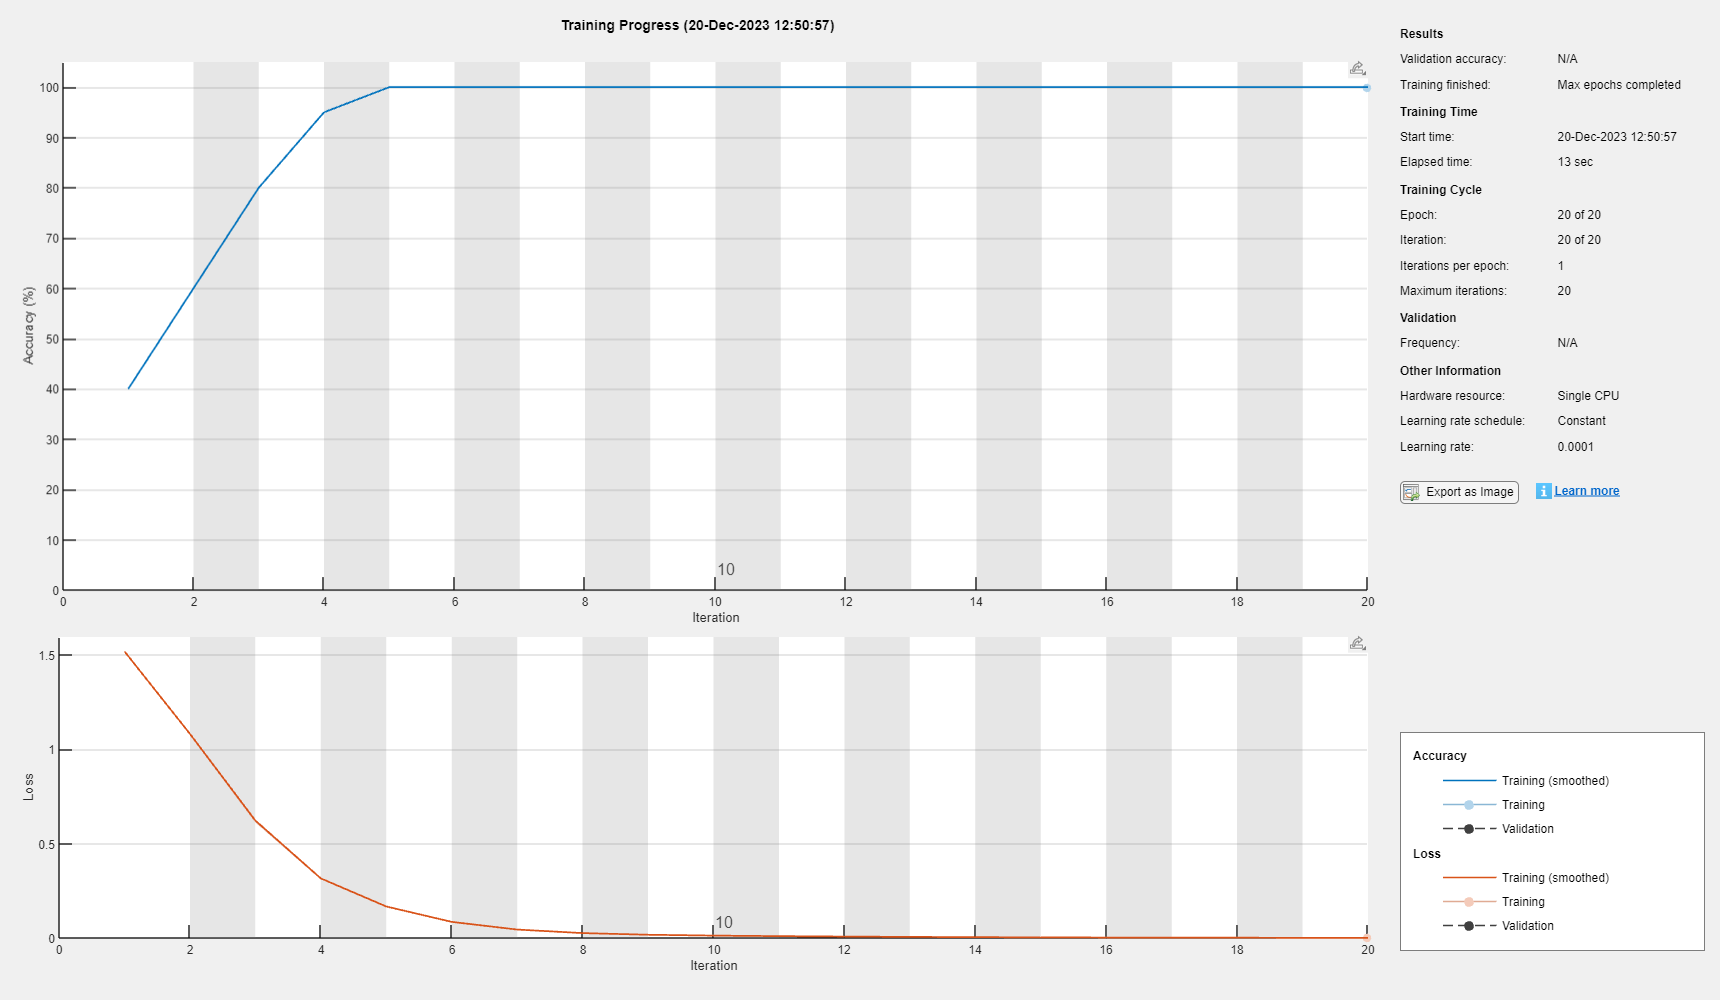

net = trainNetwork(imdsTrain,layers,options);

Ejecutar la red entrenada en el conjunto de prueba, que no se utilizó para entrenar la red, y predecir las etiquetas de las imágenes.

YPred = classify(net,imdsValidation);
YTest = imdsValidation.Labels;

Calcular la precisión. La precisión es la proporción del número de etiquetas verdaderas en los datos de prueba que coinciden con las clasificaciones de `classify` con respecto al número de imágenes en los datos de prueba.

accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9524

Probar con una imagen la red:

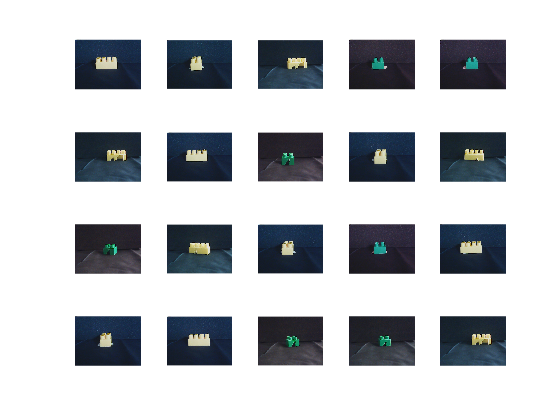

% Ruta de la imagen que deseas clasificar
imagen_a_clasificar = imread('imagen.jpg'); % Cambia 'ruta_de_la_imagen.jpg' por la ruta correcta de tu imagen
% 
% % Mostrar la imagen
imshow(imagen_a_clasificar);



% % Realizar la predicción
etiqueta_predicha = classify(net, imagen_a_clasificar);
% 
% % Mostrar la etiqueta predicha
disp(['La red predice que la imagen pertenece a la clase: ' char(etiqueta_predicha)]);

La red predice que la imagen pertenece a la clase: rectangulo_roto


*Copyright 2012 The MathWorks, Inc.*